# Exercise 2 regbot

## Plot data from the log txt file

data = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_4\regbot_log_4.txt');
data = fillmissing(data, 'nearest');

t = table2array(data(:,1));     % time stamps
u_L = table2array(data(:,8));   % left motor voltage
u_R = table2array(data(:,9));   % right motor voltage
v_L = table2array(data(:,10));  % left motor velocity 
v_R = table2array(data(:,11));  % right motor velocity
T_s = t(2) - t(1);              % compute sampling time

%Trim data
% Find the index where X becomes 3 for the first time
idx = find(u_L >= 3,1,'first');   
% Keep only the data after this index
u_L = u_L(idx:end); 
v_L = v_L(idx:end);
u_R = u_R(idx:end); 
v_R = v_R(idx:end);
% Do the same for the time vector
t = t(idx:end);                 
t = t - t(1);

vel = 1/2*(v_L + v_R);          % average wheel velocity
volt = 1/2*(u_L + u_R);         % average voltage

idd_L = iddata(v_L,u_L,T_s);    % Prepare left wheel data
idd_R = iddata(v_R,u_R,T_s);    % Prepare right wheel data
idd_A = iddata(vel,volt,T_s);    % Prepare average wheel data

G_wu_L = tfest(idd_L,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_L =
 
  From input "u1" to output "y1":
         337.9
  --------------------
  s^2 + 98.62 s + 1134
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_L".
Fit to estimation data: 87.13%                    
FPE: 0.0007706, MSE: 0.0007626                    


G_wu_R = tfest(idd_R,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_R =
 
  From input "u1" to output "y1":
         4.449e04
  ----------------------
  s^2 + 7580 s + 1.38e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_R".
Fit to estimation data: 92.43%                    
FPE: 0.0002796, MSE: 0.0002767                    


G_wu_A = tfest(idd_A,2,0)      % Identify left wheel transfer function (2 poles, no zeros - you can try other combinations)

G_wu_A =
 
  From input "u1" to output "y1":
            7.47e04
  ---------------------------
  s^2 + 1.399e04 s + 2.414e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_A".
Fit to estimation data: 89.66%                    
FPE: 0.0005091, MSE: 0.0005038                    


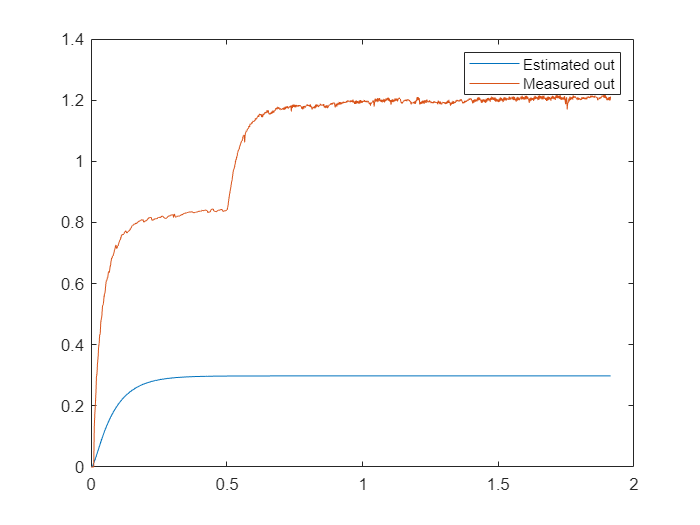

v_L_out = v_L - v_L(1);

[y_L,t_L] = step(G_wu_L,t(end));
plot(t_L,y_L);
hold on;
plot(t,v_L_out);
hold off;
legend('Estimated out','Measured out');


sys = tfest(idd_A,2,1)

sys =
 
  From input "u1" to output "y1":
     7.221 s + 14.2
  --------------------
  s^2 + 25.8 s + 45.06
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "idd_A".
Fit to estimation data: 96.21%                    
FPE: 6.841e-05, MSE: 6.755e-05                    


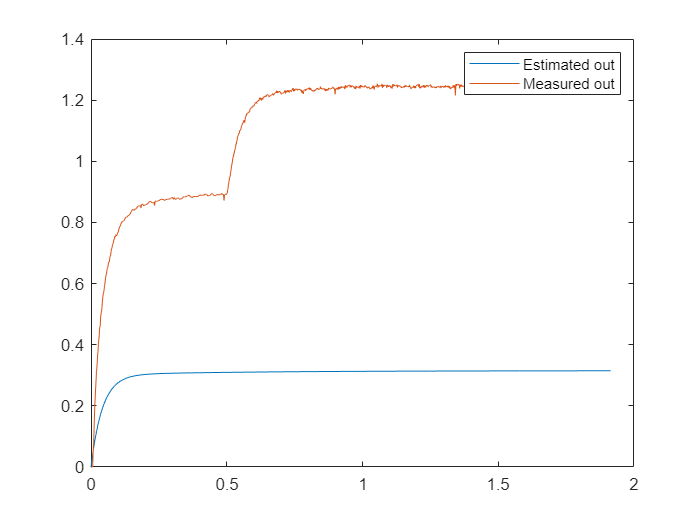

[y_A,t_A] = step(sys,t(end));
plot(t_A,y_A);
hold on;
plot(t,vel);
hold off;
legend('Estimated out','Measured out');